# Operational Amplifiers Lab

[⇦ DC Circuit Analysis Overview](matlab: OpenOverview)

In this lab, you will design circuits that perform mathematical computations using op amp circuits.

### Part 1. Implement an op amp circuit

In this section, you will simulate a circuit that computes


$$V_{out} = - 4V_{in} + 0.02 \frac{dV_{in}}{dt}$$


using op amps. Follow the steps below to design the circuit. 

For the derivative term, you can use a differentiator circuit. 

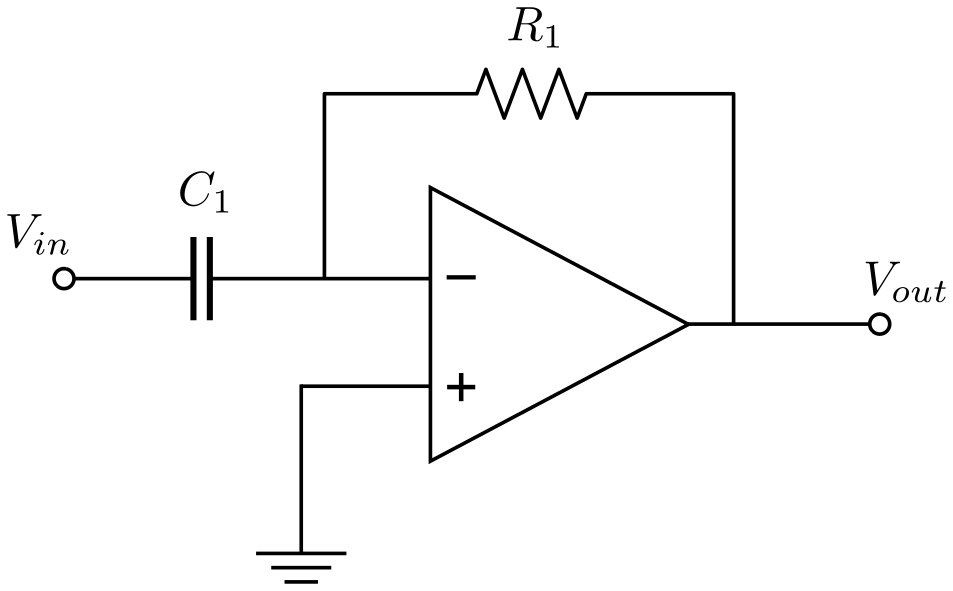

*Differentiator*

The differentiator produces an output of


$$V_{out} = -R_1C_1 \frac{dV_{in}}{dt}$$


**Task 1.** Using a capacitor with $C_1 = 10$ $\mu \text{F}$, what resistor value should be used (in $\text{k} \Omega$) to produce a gain magnitude of 0.02?

R1_part1 = 2 % Replace NaN with your answer in kOhm

R1_part1 = 2

**Task 2.** To combine the two terms of the equation, you can use an inverted summing amplifier.

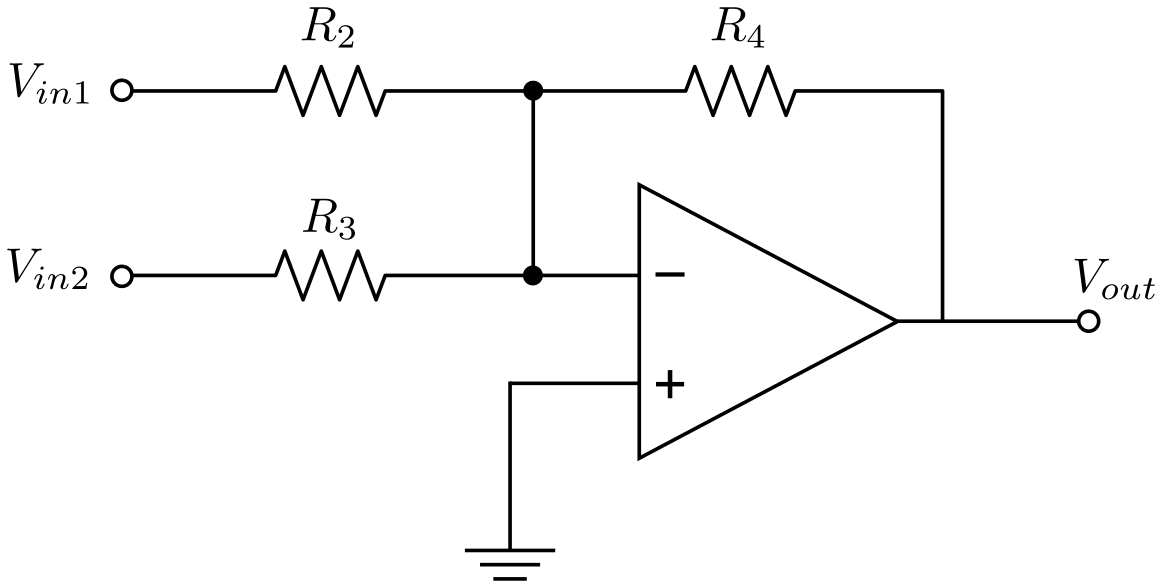

*Inverting Summing Amplifier*

The inverting summing amplifier produces an output of


$$V_{out} = -\frac{R_4}{R_2} V_{in1} -\frac{R_4}{R_3} V_{in2}$$


Suppose that $R_3 = R_4 = 4$$\text{k} \Omega$ and $V_{in2}$ is the output of the derivative stage derived above. What value of $R_2$ will produce the desired output $V_{out}$?

R2_part1 = 1 % Replace NaN with your answer kOhm

R2_part1 = 1

**Task 3. **The combined circuit is shown below.

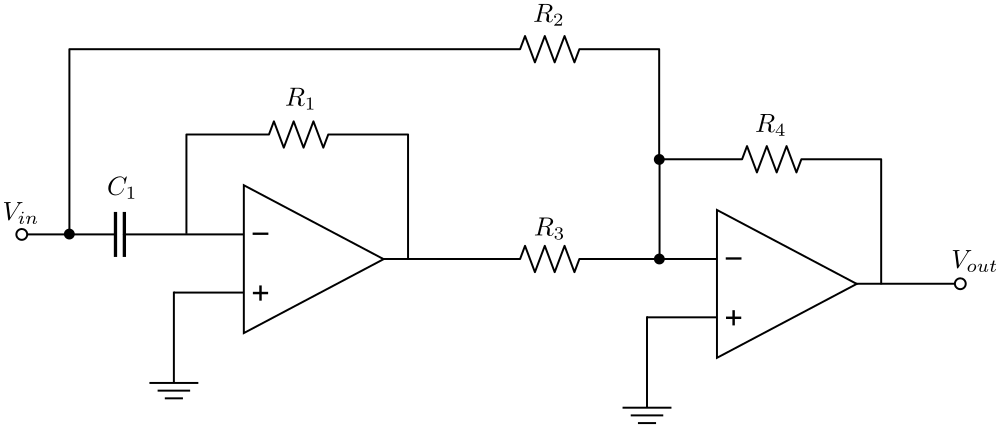

*Combined Circuit*

Use the link to open the Simscape model and construct the circuit.

[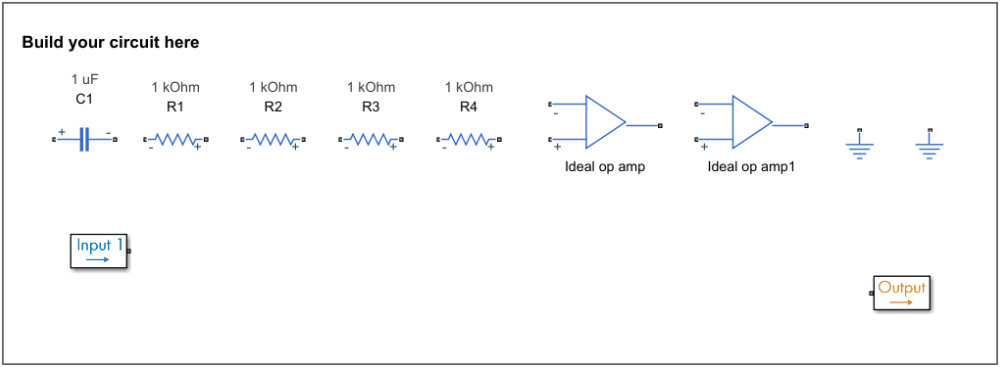](matlab: OpAmpLab)

[`OpAmpLab.slx`](matlab: OpAmpLab)

Set the controls to use a triangle wave source (the model has a default frequency of 60 Hz) with a magnitude of 1 V. Run this section of the live script. If your model is correct, the output should match the graph of $V_{out}$ generated below.

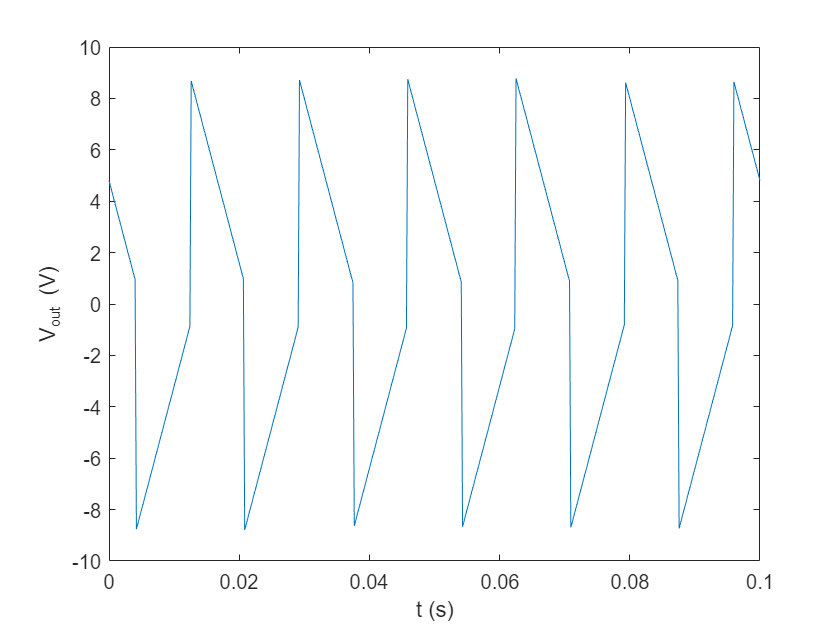

% Simulate the response
syms t
Vin = 2/pi*asin( sin(2*pi*60*t) );
dVindt = diff(Vin);
Vout = -4*Vin + 0.02*dVindt;

% Plot the response
tvec = linspace(0,0.1,500);
plot(tvec,subs(Vout,t,tvec))
ylim([-10 10])
xlabel("t (s)")
ylabel("V_{out} (V)")

### Part 2. Solve an ODE with op amps

In this section, you will solve an ODE using op amp circuits. Consider the forced ODE:


$$-\dot{x} =-10x -1000u$$


where $u$ is an arbitrary input function. Let $u = V_{in}$, the input to your op amp circuit. You can solve the ODE with op amps using an integrator and an inverting summing amplifier. The integrator circuit produces an output of


$$V_{out} = - \frac{1}{R_1 C_1} \int  V_{in} \ dt$$


Recall that the inverting summing amplifier produces an output of


$$V_{out} = -\frac{R_4}{R_2} V_{in1} -\frac{R_4}{R_3} V_{in2}$$


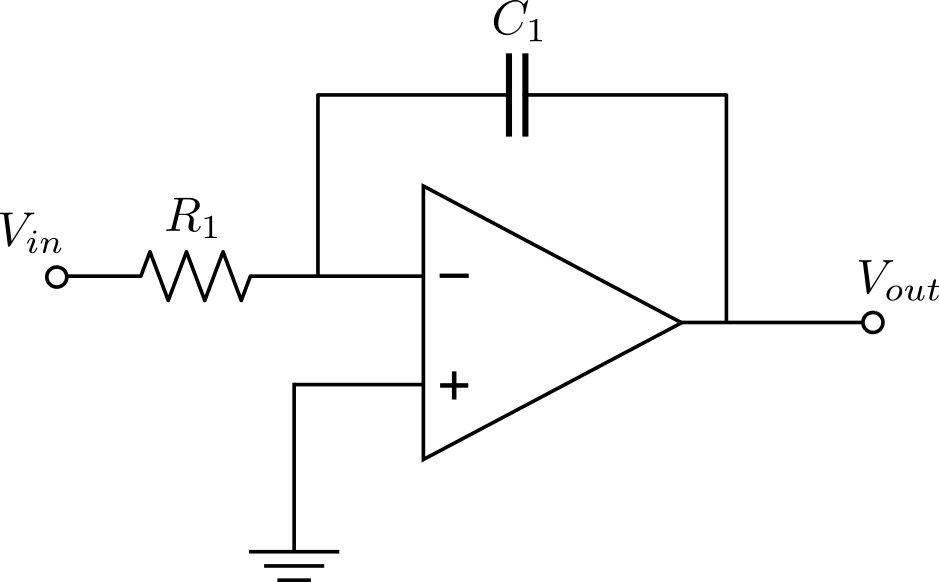                    

*Integrator                                                               Inverting Summing Amplifier*

**Task 1. **On paper, arrange and connect the two circuits so that the combined circuit solves the ODE. The output of the circuit should be the solution to the ODE: $V_{out} = x$.

The signs are tricky, but the original equation has been arranged so that it can be solved using only these two op amp circuits. While building the circuit, carefully mark each signal with the variable it represents in the original equation along with the sign. Suppose that the $C_1 = 1$ $\mu \text{F}$ and $R_4 = 1$$\text{M} \Omega$, what value of $R_1$, $R_2$, and $R_3$ should be used in the circuits? 

R1_part2 = 1000; % kOhm
R2_part2 = 1;    % kOhm
R3_part2 = 100;  % kOhm
% Solution note: this is the most likely solution, but other choices would
% work as long as the necessary proportions are preserved

**Task 2. **Use the link to open the model. Implement the circuit in Simscape and run the model with an AC input and a magnitude of 1 V. By default, this is equivalent to an input forcing function of $u = \sin ( \omega_0 t )$ with $\omega_0 = 120 \pi$. 

[](matlab: OpAmpLab)

[`OpAmpLab.slx`](matlab: OpAmpLab)

**Task 3. **Run this section of the script. The generated plot below shows the solution to the ODE $x(t)$ over 1 second. Does this solution match $V_{out}$ generated by your circuit?

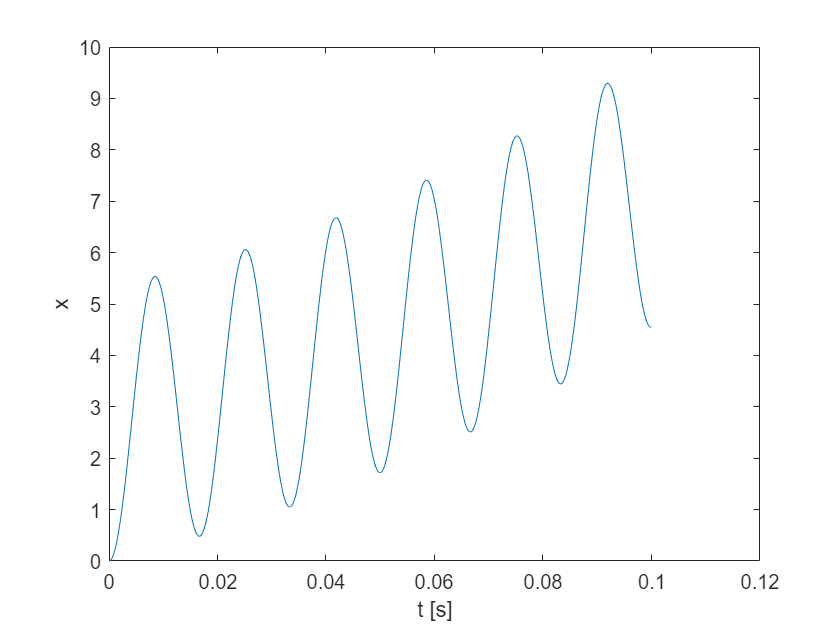

% Simulate the response
t = linspace(0,0.1,5e3);
u = 1000*sin(2*pi*60*t);
G = tf([0 1],[1 -10]);
[xsim,tsim] = lsim(G,u,t);

% Plot the response
plot(tsim,xsim)
xlabel("t [s]")
ylabel("x")

[⇦ DC Circuit Analysis Overview](matlab: OpenOverview)